**1. ****음함수의 전미분 (Total Derivative)****:**

- 함수 $u(x, y)$의 전미분은 다음과 같이 정의됩니다:$du = \frac{\partial u}{\partial x} dx + \frac{\partial u}{\partial y} dy$

여기서:

- $M(x, y) = \frac{\partial u}{\partial x}$�

- $N(x, y) = \frac{\partial u}{\partial y}$�

- 이는 x와 y가 동시에 변화할 때 함수$u(x, y)$의 총 변화량을 나타냅니다.

- 예시로 주어진 함수$u(x, y) = 4x^2 y$에 대해서:

- 
$$\frac{\partial u}{\partial x} = 8xy$$


- 
$$\frac{\partial u}{\partial y} = 4x^2$$


% 심볼릭 변수 설정
syms x y

% 주어진 함수 u(x, y)
u = 4*x^2*y;

% x에 대한 부분 미분
du_dx = diff(u, x);

% y에 대한 부분 미분
du_dy = diff(u, y);

% 결과 출력
disp('x에 대한 부분 미분 (du/dx):');

x에 대한 부분 미분 (du/dx):


disp(du_dx);

$$8\,x\,y$$


disp('y에 대한 부분 미분 (du/dy):');

y에 대한 부분 미분 (du/dy):


disp(du_dy);

$$4\,x^{2}$$


% 전미분 구하기
du_total = du_dx*diff(x) + du_dy*diff(y);
disp('전미분 (du):');

전미분 (du):


disp(du_total);

$$4\,x^{2}+8\,y\,x$$

**2. ****포텐셜 함수 (Potential Function)****:**

- 포텐셜 함수는 전미분이 0인 함수로 정의됩니다: $u(x, y) = c \quad (\text{상수})$

- 이때 전미분: $du = \frac{\partial u}{\partial x} dx + \frac{\partial u}{\partial y} dy = 0$

- 이는 즉, 모든 미분값이 0이 되는 상수 함수를 의미합니다.

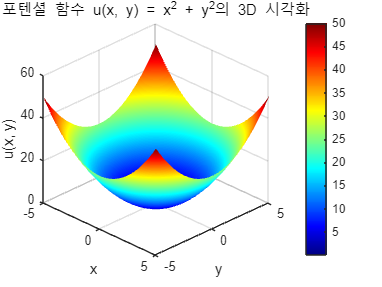

% x와 y의 범위 설정
x = linspace(-5, 5, 100);  % x축 범위
y = linspace(-5, 5, 100);  % y축 범위

% x와 y의 그리드 생성
[X, Y] = meshgrid(x, y);

% 포텐셜 함수 u(x, y) 계산
U = X.^2 + Y.^2;

% 포텐셜 함수의 3D 시각화
figure;
surf(X, Y, U);  % 3D 표면 그래프 그리기

% 그래프 레이블 및 제목 설정
xlabel('x');
ylabel('y');
zlabel('u(x, y)');
title('포텐셜 함수 u(x, y) = x^2 + y^2의 3D 시각화');

% 그래프 스타일 설정
colormap jet;  % 색상 설정
shading interp;  % 그래프 부드럽게
colorbar;  % 색상 표시 바 추가

% 보기 각도 조정 (필요시)
view(45, 30);  % 시각화 각도 설정

**1. ****완전 상미분방정식의 형태****:**

주어진 1계 상미분방정식은 다음과 같이 나타낼 수 있습니다:


$$M(x, y) + N(x, y) y' = 0$$


이를 다음과 같이 다시 쓸 수 있습니다:


$$M(x, y) dx + N(x, y) dy = 0$$


**2. ****포텐셜 함수의 존재****:**

방정식$M(x, y) dx + N(x, y) dy = 0$가 **완전 상미분방정식**이 되기 위한 조건은, 포텐셜 함수 $u(x, y)$가 어떤 영영 R에서 존재하여 해당 미분방정식이 **완전 미분**으로 표현될 수 있는 경우입니다. 

즉, 특정 함수 $u(x, y)$가 존재하여:


$$\frac{\partial u}{\partial x} = M(x, y), \quad \frac{\partial u}{\partial y} = N(x, y)$$
 


$$du = \frac{\partial u}{\partial x} dx + \frac{\partial u}{\partial y} dy $$


이 조건을 만족하면, 주어진 방정식은 완전 상미분방정식이 됩니다.

% 심볼릭 변수 설정
syms x y u(x, y)

% M(x, y)와 N(x, y)를 설정 (예: M(x, y) = 2xy, N(x, y) = x^2)
M = 2*x*y;  % M(x, y)
N = x^2;    % N(x, y)

% M과 N이 완전 미분방정식이 되는지 확인하기 위해
% M의 y에 대한 부분 미분과 N의 x에 대한 부분 미분을 계산
dM_dy = diff(M, y);
dN_dx = diff(N, x);

% 결과 확인
disp('M의 y에 대한 부분 미분:');

M의 y에 대한 부분 미분:


disp(dM_dy);

$$2\,x$$


disp('N의 x에 대한 부분 미분:');

N의 x에 대한 부분 미분:


disp(dN_dx);

$$2\,x$$


% 두 미분이 같으면 완전 상미분방정식임
if dM_dy == dN_dx
    disp('완전 상미분방정식입니다.');
else
    disp('완전 상미분방정식이 아닙니다.');
end

완전 상미분방정식입니다.


**완전 상미분방정식의 형태**

$M(x, y)dx + N(x, y)dy = 0$ 이 완전 상미분방정식

해 : $u(x, y) = c  $로 음함수 형태가 됨

#### `완전 상미분방정식의 판정 조건(매우중요)``:`

주어진 방정식 $M(x, y)dx + N(x, y)dy = 0$이 **완전 상미분방정식**이 되기 위한 필요충분조건은 다음과 같습니다:

$\frac{\partial M}{\partial y} = \frac{\partial N}{\partial x}$�

즉, $M(x, y)$를 y에 대해 미분한 값이 $N(x, y)$를 x에 대해 미분한 값과 같으면, 이 방정식은 완전 상미분방정식입니다.

**예시 방정식:**$x^2 + 3xy + (4xy + 2x)y' = 0$

이 방정식에서:

- 
$$M(x, y) = x^2 + 3xy$$


- 
$$N(x, y) = 4xy + 2x$$


% 심볼릭 변수 설정
syms x y

% M(x, y)와 N(x, y) 정의
M = x^2 + 3*x*y;
N = 4*x*y + 2*x;

% M의 y에 대한 부분 미분
dM_dy = diff(M, y);

% N의 x에 대한 부분 미분
dN_dx = diff(N, x);

% 결과 출력
disp('M의 y에 대한 부분 미분:');

M의 y에 대한 부분 미분:


disp(dM_dy);

$$3\,x$$


disp('N의 x에 대한 부분 미분:');

N의 x에 대한 부분 미분:


disp(dN_dx);

$$4\,y+2$$


% 완전 상미분방정식 여부 확인
if dM_dy == dN_dx
    disp('이 방정식은 완전 상미분방정식입니다.');
else
    disp('이 방정식은 완전 상미분방정식이 아닙니다.');
end

이 방정식은 완전 상미분방정식이 아닙니다.


**1. ****완전 상미분방정식****:**

주어진 미분방정식 $M(x, y) dx + N(x, y) dy = 0$이 **완전 상미분방정식**이 되기 위한 조건은 다음과 같습니다:


$$\frac{\partial u}{\partial x} = M(x, y), \quad \frac{\partial u}{\partial y} = N(x, y)$$


이 조건을 만족하는 함수$u(x, y)$가 존재하면, 방정식은 완전 상미분방정식이 됩니다.

**2. ****해법 1 – x****에 대해 적분하여 구하기****:**

- 먼저 $M(x, y)$를 x에 대해 적분하여 $u(x, y)$를 구합니다:$u = \int M dx + k(y)$여기서 $k(y)$는 x와 무관한 상수 함수입니다.

- 그 후, u를 y에 대해 미분하여 $N(x, y)$와 일치하도록 $k(y)$를 구합니다:$\frac{\partial u}{\partial y} = N(x, y)$이를 통해$k(y)$를 결정합니다.

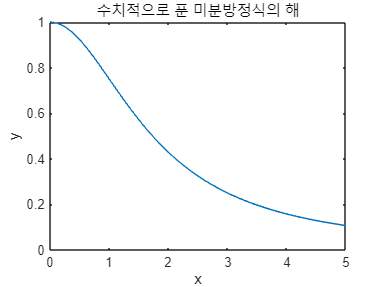

% 심볼릭 변수 설정
syms x y

% 예시: M(x, y)와 N(x, y) 설정
M = 2*x*y;  % M(x, y)
N = x^2 + 3;  % N(x, y)

% 수치적으로 방정식을 풀기 위한 도구 설정
% M과 N을 기반으로 dy/dx 형태의 방정식 작성
dy_dx = -M/N;

% 초기 조건 설정 (필요에 따라 변경)
x0 = 0;
y0 = 1;

% ode45를 사용하여 수치적으로 풀기
f = matlabFunction(dy_dx);  % 수치적 함수로 변환
[x_vals, y_vals] = ode45(f, [x0, 5], y0);  % x=0에서 x=5까지 y 값 구하기

% 결과 출력
plot(x_vals, y_vals);
xlabel('x');
ylabel('y');
title('수치적으로 푼 미분방정식의 해');


$$(2x+y^2)dx+2xydy=0$$


이 방정식은 **완전 미분방정식**으로 해결할 수 있습니다. 

이를 풀기 위해 $N(x, y)$를 y에 대해 적분하고, $M(x, y)$와 비교하여$k(x)$를 구하는 과정으로 해를 찾을 수 있습니다.

**1. 주어진 미분방정식**

- 
$$M(x, y) = 2x + y^2$$


- 
$$N(x, y) = 2xy$$


**2. 해법**

- $u(x, y)$는 완전 미분방정식의 포텐셜 함수로, 다음 과정을 통해 구합니다. $u(x, y) = \int N(x, y) dy + k(x)$먼저 $N(x, y)$를 y에 대해 적분하고, 그 결과를 이용해 $M(x, y)$를 만족하도록 $k(x)$를 구합니다.

% 심볼릭 변수 선언
syms x y C

% M(x, y)와 N(x, y) 정의
M = 2*x + y^2;   % M(x, y)
N = 2*x*y;       % N(x, y)

% M을 x에 대해 적분하여 ψ 구하기
psi_x = int(M, x);  % x에 대한 적분
disp('ψ(x, y) after integrating M with respect to x:');

ψ(x, y) after integrating M with respect to x:


disp(psi_x);

$$x\,\left(y^{2}+x\right)$$


% ψ(x, y) = x^2 + y^2*x + f(y), 여기서 f(y)는 y에 대한 함수
% 따라서, ψ(x, y)는 다음과 같이 표현됨:
syms f(y)
psi_x = x^2 + y^2*x + f(y);
disp('ψ(x, y) after adding f(y):');

ψ(x, y) after adding f(y):


disp(psi_x);

$$f\left(y\right)+x\,y^{2}+x^{2}$$


% ψ를 y에 대해 미분하고, 이를 N(x, y)와 비교
d_psi_dy = diff(psi_x, y);  % y에 대해 미분
disp('dψ/dy (y에 대해 미분):');

dψ/dy (y에 대해 미분):


disp(d_psi_dy);

$$\frac{\partial }{\partial y}f\left(y\right)+2\,x\,y$$


% dψ/dy = N(x, y) = 2xy 이므로 f'(y) = 0
% 따라서, f(y)는 상수 함수임 (f(y) = C)

% 최종적으로, ψ(x, y)는 다음과 같음
psi_final = x^2 + y^2*x + C;
disp('Final solution ψ(x, y):');

Final solution ψ(x, y):


disp(psi_final);

$$x^{2}+x\,y^{2}+C$$


% 이 방정식의 해는 암시적 해로, x^2 + y^2*x = C


포텐셜 함수 $u(x, y) = x^2 + xy^2 = C$

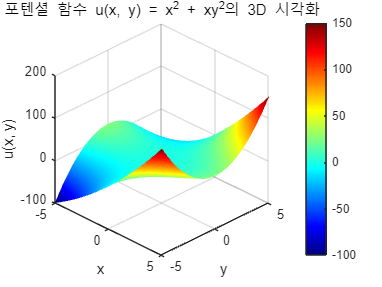

% x와 y의 범위 설정
x = linspace(-5, 5, 100);  % x축 범위
y = linspace(-5, 5, 100);  % y축 범위

% x와 y의 그리드 생성
[X, Y] = meshgrid(x, y);

% 포텐셜 함수 u(x, y) 계산
U = X.^2 + X.*Y.^2;

% 포텐셜 함수의 3D 시각화
figure;
surf(X, Y, U);  % 3D 표면 그래프 그리기

% 그래프 레이블 및 제목 설정
xlabel('x');
ylabel('y');
zlabel('u(x, y)');
title('포텐셜 함수 u(x, y) = x^2 + xy^2의 3D 시각화');

% 그래프 스타일 설정
colormap jet;  % 색상 설정
shading interp;  % 그래프 부드럽게
colorbar;  % 색상 표시 바 추가

% 보기 각도 조정 (필요시)
view(45, 30);  % 시각화 각도 설정


$$(3x-2y)dx-(2x-3y)dy=0 , y(0)=2$$


이식을 만족하는 y의 일반해는 무엇인가?

% 심볼릭 변수 선언
syms x y C

% M(x, y)와 N(x, y)를 정의
M = 3*x - 2*y;   % M(x, y)
N = -(2*x - 3*y);   % N(x, y)

% M을 x에 대해 적분하여 ψ 구하기
psi_x = int(M, x);  % x에 대한 적분
disp('ψ(x, y) after integrating M with respect to x:');

ψ(x, y) after integrating M with respect to x:


disp(psi_x);

$$\frac{x\,\left(3\,x-4\,y\right)}{2}$$


% 적분 상수로써 y에 대한 함수 f(y) 추가
syms f(y)
psi_x = psi_x + f(y);

% ψ를 y에 대해 미분하고, 이를 N(x, y)와 비교하여 f(y)를 구함
d_psi_dy = diff(psi_x, y);
disp('dψ/dy:');

dψ/dy:


disp(d_psi_dy);

$$\frac{\partial }{\partial y}f\left(y\right)-2\,x$$


% f'(y) 구하기: N과 비교
f_prime_eq = d_psi_dy == N;  % dψ/dy = N
f_solution = dsolve(f_prime_eq);  % f(y)의 해 구하기
disp('f(y):');

f(y):


disp(f_solution);

$$\frac{3\,y^{2}}{2}+C_{1}$$


% f(y)를 ψ(x, y)에 대입하여 최종 ψ 구하기
psi_final = subs(psi_x, f(y), f_solution);
disp('ψ(x, y) with f(y):');

ψ(x, y) with f(y):


disp(psi_final);

$$C_{1}+\frac{3\,y^{2}}{2}+\frac{x\,\left(3\,x-4\,y\right)}{2}$$


% 초기 조건 적용 (y(0) = 2에서 C 값 구하기)
C_value = subs(psi_final, [x, y], [0, 2]);  % x = 0, y = 2
disp('C 값:');

C 값:


disp(C_value);

$$C_{1}+6$$


% 최종 해는 ψ(x, y) = C 이므로, C를 적용한 방정식을 구하기
final_solution = psi_final == C_value;
disp('최종 해:');

최종 해:


disp(simplify(final_solution));

$$3\,x^{2}+3\,y^{2}=4\,x\,y+12$$


% 결과를 시각화하거나 분석할 수 있습니다.

**1. ****완전 미분 방정식인지 확인****:**

주어진 방정식이 완전 미분 방정식인지 확인하기 위해, 아래의 형태로 정리합니다:


$$M(x, y) = 3x - 2y \quad \text{and} \quad N(x, y) = -(2x - 3y)$$


완전 미분 방정식이려면 다음 조건을 만족해야 합니다:


$$\frac{\partial M}{\partial y} = \frac{\partial N}{\partial x}$$



$$\frac{\partial}{\partial y}(3x - 2y) = -2
$$



$$\frac{\partial}{\partial x}(-(2x - 3y)) = -2$$


두 식이 동일하므로, 이 방정식은 **완전 미분 방정식**입니다.

**2. ****해 구하기****:**

완전 미분 방정식의 해를 구하기 위해, 함수 $\psi(x, y)$를 다음 조건에 맞게 찾습니다:

$\frac{\partial \psi}{\partial x} =M(x,y)=3x-2y $ and $\frac{\partial \psi}{\partial x} =N(x,y)=-(2x-3y)$

**첫 번째 단계: **$\frac{\partial \psi}{\partial x} = M(x, y)$**로부터 **$\psi(x, y)$** 구하기:**


$$\frac{\partial \psi}{\partial x} = 3x - 2y$$


이를 x에 대해 적분하면:


$$\psi(x, y) = \frac{3}{2}x^2 - 2xy + g(y)$$


여기서 $g(y)$는 y에 대한 함수입니다. 이제$g(y)$를 구해야 합니다.

**두 번째 단계: **$\frac{\partial \psi}{\partial y} = N(x, y)$**로부터 **$g(y)$** 구하기:**$\frac{\partial \psi}{\partial y} = -2x + g'(y)$

이 식을 $N(x, y) = -(2x - 3y)$와 비교하면:


$$-2x + g'(y) = -(2x - 3y)$$


따라서,


$$g'(y) = 3y$$


이를 적분하면:


$$g(y) = \frac{3}{2}y^2 + C$$


**3. ****일반 해****:**

따라서 $\psi(x, y)$는 다음과 같습니다:


$$\psi(x, y) = \frac{3}{2}x^2 - 2xy + \frac{3}{2}y^2 + C$$


이 방정식의 해는 다음과 같습니다:


$$\frac{3}{2}x^2 - 2xy + \frac{3}{2}y^2 = C$$


**4. ****초기 조건 적용****:**

초기 조건$y(0) = 2$를 적용하면, $x = 0$일 때 $y = 2$입니다. 이를 해에 대입하여 상수 C를 구합니다:


$$\frac{3}{2}(0)^2 - 2(0)(2) + \frac{3}{2}(2)^2 = C$$



$$C = \frac{3}{2}(4) = 6$$


따라서, $C = 6$입니다.

**최종 해:**

따라서, 이 미분 방정식의 해는 다음과 같습니다:


$$\frac{3}{2}x^2 - 2xy + \frac{3}{2}y^2 = 6$$


이것이 y의 일반 해입니다.

#### $\frac{3}{2}x^2 - 2xy + \frac{3}{2}y^2 = 6
$` 의 포텐셜 함수`

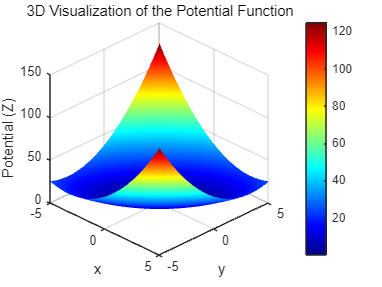

% x와 y의 범위 설정
x = linspace(-5, 5, 100);  % x축 범위
y = linspace(-5, 5, 100);  % y축 범위

% 그리드 생성
[X, Y] = meshgrid(x, y);

% 주어진 방정식의 z 값 계산 (포텐셜 함수로 변환)
Z = (3/2)*X.^2 - 2*X.*Y + (3/2)*Y.^2;

% 3D 표면 그래프 그리기
figure;
surf(X, Y, Z);

% 그래프 설정
xlabel('x');
ylabel('y');
zlabel('Potential (Z)');
title('3D Visualization of the Potential Function');
colormap jet;  % 색상 설정
shading interp;  % 부드러운 색상 변화
colorbar;  % 색상 바 추가
grid on;

% 보기 각도 조정
view(45, 30);